clear; close all; clc;

m = 0.064;       % kg
kT = 1.0;        % thrust per unit (placeholder)
Ka = kT / m;     % altitude plant gain
Kr = 70.0;       % roll/pitch plant gain (placeholder)
Kyaw = 20.0;     % yaw plant gain placeholder (smaller than roll typically)
Ta = 0.02;       % actuator lag (s) - include ESC/motor first-order lag

s = tf('s');

% plants: angle/altitude double-integrators with actuator lag
G_roll  = series(1/(Ta*s + 1), Kr/(s^2));
G_pitch = series(1/(Ta*s + 1), Kr/(s^2));
G_yaw   = series(1/(Ta*s + 1), Kyaw/(s^2));
G_alt   = series(1/(Ta*s + 1), Ka/(s^2));



## Controller sets


% 1) GUI defaults (from your screenshots)
GUI.Kp_roll = 4.0;    GUI.Ki_roll = 0.010; GUI.Kd_roll = 30.0;
GUI.Kp_pitch= 4.0;    GUI.Ki_pitch= 0.010; GUI.Kd_pitch= 30.0;
GUI.Kp_yaw  = 15.0;   GUI.Ki_yaw  = 0.070; GUI.Kd_yaw  = 50.0;
GUI.Kp_alt  = 10.0;   GUI.Ki_alt  = 0.000; GUI.Kd_alt  = 30.0;

% Build GUI controllers (continuous)
Cgui.roll  = GUI.Kd_roll  * s + GUI.Kp_roll  + GUI.Ki_roll  / s;
Cgui.pitch = GUI.Kd_pitch * s + GUI.Kp_pitch + GUI.Ki_pitch / s;
Cgui.yaw   = GUI.Kd_yaw   * s + GUI.Kp_yaw   + GUI.Ki_yaw   / s;
Cgui.alt   = GUI.Kd_alt   * s + GUI.Kp_alt   + GUI.Ki_alt   / s;

% 2) Recommended (design via target wn & zeta)
zeta = 0.7;
% Choose target natural frequencies (rad/s) reasonably:
wn_roll  = 20;   % ~3.2 Hz (fairly responsive inner attitude)
wn_pitch = 20;   % same as roll (symmetric)
wn_yaw   = 8;    % yaw typically slower
wn_alt   = 2;    % altitude outer loop slower (~0.3 Hz)

% Solve Kp, Kd from wn and zeta for double-integrator plant: Kp = wn^2 / K, Kd = 2*zeta*wn / K
REC.Kp_roll  = wn_roll^2  / Kr;        REC.Kd_roll  = (2*zeta*wn_roll)/Kr;  REC.Ki_roll = 0;
REC.Kp_pitch = wn_pitch^2 / Kr;       REC.Kd_pitch = (2*zeta*wn_pitch)/Kr; REC.Ki_pitch= 0;
REC.Kp_yaw   = wn_yaw^2   / Kyaw;     REC.Kd_yaw   = (2*zeta*wn_yaw)/Kyaw;  REC.Ki_yaw  = 0;
REC.Kp_alt   = wn_alt^2   / Ka;       REC.Kd_alt   = (2*zeta*wn_alt)/Ka;    REC.Ki_alt  = 0.1; % small integral for altitude

% Build recommended controllers
Crec.roll  = REC.Kd_roll  * s + REC.Kp_roll  + REC.Ki_roll  / s;
Crec.pitch = REC.Kd_pitch * s + REC.Kp_pitch + REC.Ki_pitch / s;
Crec.yaw   = REC.Kd_yaw   * s + REC.Kp_yaw   + REC.Ki_yaw   / s;
Crec.alt   = REC.Kd_alt   * s + REC.Kp_alt   + REC.Ki_alt   / s;

%% Closed-loop transfer functions (unity feedback)

T.gui.roll  = feedback(series(Cgui.roll,  G_roll), 1);
T.gui.pitch = feedback(series(Cgui.pitch, G_pitch),1);
T.gui.yaw   = feedback(series(Cgui.yaw,   G_yaw),  1);
T.gui.alt   = feedback(series(Cgui.alt,   G_alt),  1);

T.rec.roll  = feedback(series(Crec.roll,  G_roll), 1);
T.rec.pitch = feedback(series(Crec.pitch, G_pitch),1);
T.rec.yaw   = feedback(series(Crec.yaw,   G_yaw),  1);
T.rec.alt   = feedback(series(Crec.alt,   G_alt),  1);

%% Print poles & time constants

fprintf('\nPoles and dominant time-constants (GUI controllers):\n');


Poles and dominant time-constants (GUI controllers):


fields = {'roll','pitch','yaw','alt'};
for f = fields
    P = pole(T.gui.(f{1}));
    fprintf('%6s poles: ', f{1}); fprintf(' %.4e', P); fprintf('\n');
    % time constants (positive) for stable negative real parts
    tc = 1./(-real(P(real(P)<0)));
    if ~isempty(tc), fprintf('  time consts (s):'); fprintf(' %.6f', tc); end
    fprintf('\n');
end

  roll poles:  -2.4933e+01 -2.4933e+01 -1.3079e-01 -2.5487e-03


  time consts (s): 0.040107 0.040107 7.645675 392.353850

 pitch poles:  -2.4933e+01 -2.4933e+01 -1.3079e-01 -2.5487e-03


  time consts (s): 0.040107 0.040107 7.645675 392.353850

   yaw poles:  -2.4850e+01 -2.4850e+01 -2.9535e-01 -4.7416e-03


  time consts (s): 0.040242 0.040242 3.385853 210.898867

   alt poles:  -2.4833e+01 -2.4833e+01 -3.3357e-01


  time consts (s): 0.040269 0.040269 2.997879


fprintf('\nPoles and dominant time-constants (Recommended controllers):\n');


Poles and dominant time-constants (Recommended controllers):


for f = fields
    P = pole(T.rec.(f{1}));
    fprintf('%6s poles: ', f{1}); fprintf(' %.4e', P); fprintf('\n');
    tc = 1./(-real(P(real(P)<0)));
    if ~isempty(tc), fprintf('  time consts (s):'); fprintf(' %.6f', tc); end
    fprintf('\n');
end

  roll poles:  -2.5786e+01 -1.2107e+01 -1.2107e+01


  time consts (s): 0.038781 0.082597 0.082597

 pitch poles:  -2.5786e+01 -1.2107e+01 -1.2107e+01


  time consts (s): 0.038781 0.082597 0.082597

   yaw poles:  -3.7281e+01 -6.3593e+00 -6.3593e+00


  time consts (s): 0.026823 0.157250 0.157250

   alt poles:  -4.7118e+01 -1.1534e+00 -1.1534e+00 -5.7519e-01


  time consts (s): 0.021223 0.867027 0.867027 1.738568

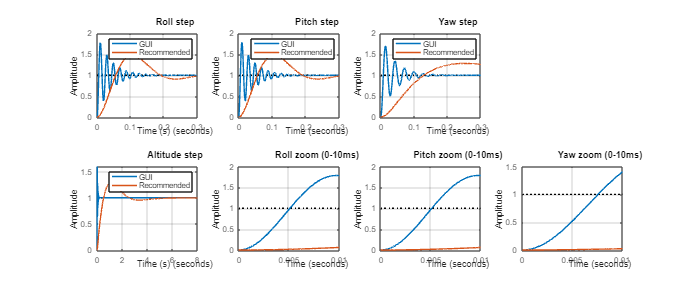


%% Plot: Closed-loop STEP responses (GUI vs Recommended)
% Time vectors chosen so we can see fast attitude transients and slower altitude

t_att = 0:1e-4:0.3;   % fine resolution for roll/pitch/yaw
t_alt = 0:1e-3:8;     % for altitude

figure('Name','Closed-loop Step Responses (GUI vs Recommended)','NumberTitle','off','Position',[100 100 1100 450]);
subplot(2,4,1); step(T.gui.roll, t_att); hold on; step(T.rec.roll, t_att); grid on;
title('Roll step'); legend('GUI','Recommended'); xlabel('Time (s)');

subplot(2,4,2); step(T.gui.pitch, t_att); hold on; step(T.rec.pitch, t_att); grid on;
title('Pitch step'); legend('GUI','Recommended');

subplot(2,4,3); step(T.gui.yaw, t_att); hold on; step(T.rec.yaw, t_att); grid on;
title('Yaw step'); legend('GUI','Recommended');

subplot(2,4,4); % combined small view
plot([0 0],[0 0]); axis off; title(' ');

subplot(2,4,5); step(T.gui.alt, t_alt); hold on; step(T.rec.alt, t_alt); grid on;
title('Altitude step'); legend('GUI','Recommended'); xlabel('Time (s)');

% For clarity also zoom small time on roll/pitch
subplot(2,4,6); step(T.gui.roll, 0:1e-5:0.01); hold on; step(T.rec.roll, 0:1e-5:0.01); grid on;
title('Roll zoom (0-10ms)');

subplot(2,4,7); step(T.gui.pitch, 0:1e-5:0.01); hold on; step(T.rec.pitch, 0:1e-5:0.01); grid on;
title('Pitch zoom (0-10ms)');

subplot(2,4,8); step(T.gui.yaw, 0:1e-5:0.01); hold on; step(T.rec.yaw, 0:1e-5:0.01); grid on;
title('Yaw zoom (0-10ms)');

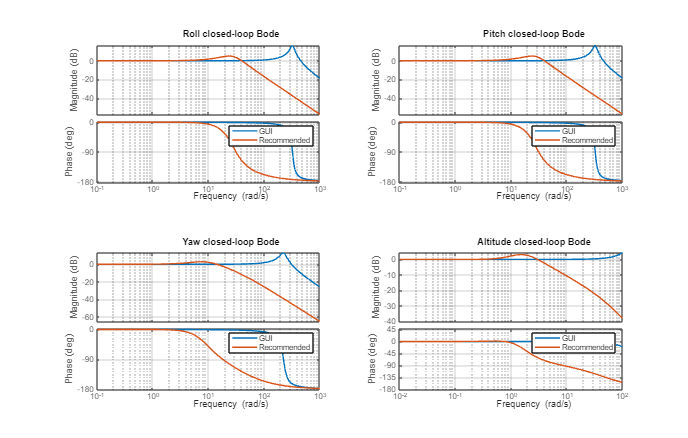


%% Plot: Closed-loop Bode plots (magnitude & phase)
figure('Name','Closed-loop Bode (GUI vs Recommended)','NumberTitle','off','Position',[120 120 1100 700]);
subplot(2,2,1);
bode(T.gui.roll, T.rec.roll, {0.1, 1000}); grid on; title('Roll closed-loop Bode');
legend('GUI','Recommended');

subplot(2,2,2);
bode(T.gui.pitch, T.rec.pitch, {0.1, 1000}); grid on; title('Pitch closed-loop Bode');
legend('GUI','Recommended');

subplot(2,2,3);
bode(T.gui.yaw, T.rec.yaw, {0.1, 1000}); grid on; title('Yaw closed-loop Bode');
legend('GUI','Recommended');

subplot(2,2,4);
bode(T.gui.alt, T.rec.alt, {0.01, 100}); grid on; title('Altitude closed-loop Bode');
legend('GUI','Recommended');



fprintf('\nPlots created. If GUI traces look instantaneous (flat), try zooming the time vector\nfor the attitude plots (very fine time resolution was included). To change target bandwidths,\nedit wn_roll/wn_pitch/wn_yaw/wn_alt or the GUI gains above and re-run.\n\n');


Plots created. If GUI traces look instantaneous (flat), try zooming the time vector
for the attitude plots (very fine time resolution was included). To change target bandwidths,
edit wn_roll/wn_pitch/wn_yaw/wn_alt or the GUI gains above and re-run.




L_alt = series(Crec_alt, G_alt);   % open-loop L(s) = C(s)G(s)

Unrecognized function or variable 'Crec_alt'.

T_alt = feedback(L_alt, 1);     % closed-loop T(s) = L/(1+L)

%% ----- Step response -----
figure;
step(T_alt, 0:0.01:5);          % simulate from 0 to 5 seconds
grid on;
title('Altitude Closed-Loop Step Response');
xlabel('Time (seconds)');
ylabel('Altitude (normalized)');

